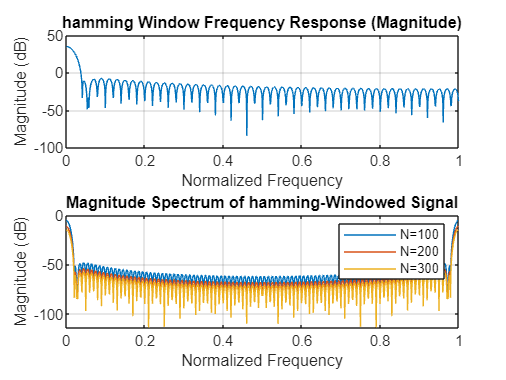

a=1+mod(230,3);
N = 100;
rectangular_window = rectwin(N);
freq_response_rectangular = freqz(rectangular_window, 1, 1024);
subplot(2, 1, 1);
plot(linspace(0, 1, 1024), 20*log10(abs(freq_response_rectangular)));
title('Rectangular Window Frequency Response (Magnitude)');
xlabel('Normalized Frequency');
ylabel('Magnitude (dB)');
grid on;

% Plot the phase of the frequency response
subplot(2, 1, 2);
plot(linspace(0, 1, 1024), angle(freq_response_rectangular));
title('Rectangular Window Frequency Response (Phase)');
xlabel('Normalized Frequency');
ylabel('Phase (radians)');
grid on;

hamming_window = hamming(N);
freq_response_hamming = freqz(hamming_window, 1, 1024);
subplot(2, 1, 1);
plot(linspace(0, 1, 1024), 20*log10(abs(freq_response_hamming)));
title('Hamming Window Frequency Response (Magnitude)');
xlabel('Normalized Frequency');
ylabel('Magnitude (dB)');
grid on;
subplot(2, 1, 2);
plot(linspace(0, 1, 1024), angle(freq_response_hamming));
title('Hamming Window Frequency Response (Phase)');
xlabel('Normalized Frequency');
ylabel('Phase (radians)');
grid on;
hamming_window = hamming(N);
freq_response_hamming = freqz(hamming_window, 1, 1024);


subplot(2, 1, 1);
plot(linspace(0, 1, 1024), 20*log10(abs(freq_response_hamming)));
title('hamming Window Frequency Response (Magnitude)');
xlabel('Normalized Frequency');
ylabel('Magnitude (dB)');
grid on;

% Plot the phase of the frequency response
subplot(2, 1, 2);
plot(linspace(0, 1, 1024), angle(freq_response_blackman));
title('Hanning Window Frequency Response (Phase)');
xlabel('Normalized Frequency');
ylabel('Phase (radians)');
grid on;

% Define the value of alpha
alpha = 3;
N_values = [100,200,300];
N_DFT = 1024;
freq_axis = (0:N_DFT-1) / N_DFT;
for N = N_values
    % Generate the hamming window
   hamming_window = hamming(N);
    t = 0:1/N:(N-1)/N;
    signal = 1;
    
    % Apply the Hamming window to the signal
    windowed_signal = signal .* (hamming_window');
    dft = fft(windowed_signal, N_DFT);
    normalized_magnitude = abs(dft) / N;
    plot(freq_axis, 20*log10(normalized_magnitude));
    hold on;
end
title('Magnitude Spectrum of hamming-Windowed Signal');
xlabel('Normalized Frequency');
ylabel('Magnitude (dB)');
legend('N=100','N=200','N=300');
grid on;
hold off;

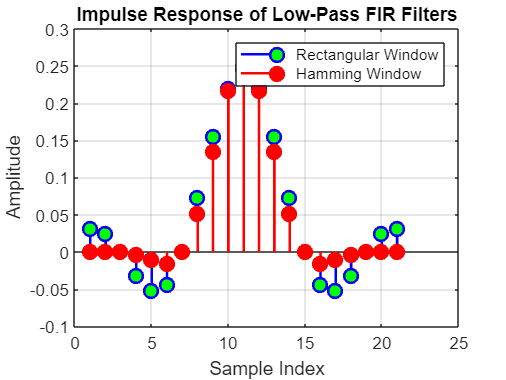

alpha = 3; % Hamming window
window_length = 21;
cutoff_frequency = pi /4;
rectangular_filter = fir1(window_length-1, cutoff_frequency/(pi), 'low', rectwin(window_length));
hamming_filter = fir1(window_length-1, cutoff_frequency/(pi), 'low', blackman(window_length));
figure;
stem(rectangular_filter, 'b', 'LineWidth', 1.5, 'MarkerSize', 8, 'MarkerFaceColor', 'g');
hold on;
stem(blackman_filter, 'r', 'LineWidth', 1.5, 'MarkerSize', 8, 'MarkerFaceColor', 'r');
hold off;
title('Impulse Response of Low-Pass FIR Filters');
xlabel('Sample Index');
ylabel('Amplitude');
legend('Rectangular Window', 'Hamming Window');
grid on;

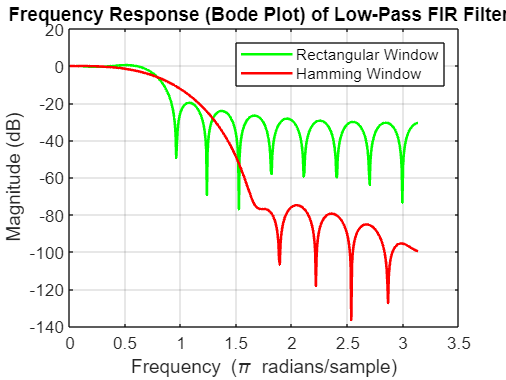

[frequency_response_rect, freq_rect] = freqz(rectangular_filter, 1, 'half');
[frequency_response_hamming, freq_hamming] = freqz(hamming_filter, 1, 'half');
figure;
plot(freq_rect, 20*log10(abs(frequency_response_rect)), 'g', 'LineWidth', 1.5);
hold on;
plot(freq_hamming, 20*log10(abs(frequency_response_hamming)), 'r', 'LineWidth', 1.5);
hold off;
title('Frequency Response (Bode Plot) of Low-Pass FIR Filters');
xlabel('Frequency (\pi radians/sample)');
ylabel('Magnitude (dB)');
legend('Rectangular Window', 'Hamming Window');
grid on;

disp('The rectangular window filter has a sharper transition band and higher stopband attenuation compared to the Blackman window filter.');

The rectangular window filter has a sharper transition band and higher stopband attenuation compared to the Blackman window filter.


[y, fs] = audioread('instru3.wav');

Error using audioread>readaudio
The filename specified was not found in the MATLAB path.

Error in audioread (line 160)
    [y, Fs] = readaudio (filename, range, datatype);

N = length(y);
dft = fft(y, N);
figure;
subplot(2, 1, 1);
spectrogram(y, hamming(512), 256, 512, fs, 'yaxis');
title('Spectrogram of original audio');
magnitude_spectrum = abs(dft);
[~, peak_index] = max(magnitude_spectrum(2:end));
fundamental_frequency = peak_index * fs / N
low_cutoff = fundamental_frequency - 20; 
high_cutoff = fundamental_frequency + 20


nyquist_freq = fs / 2;
low_cutoff_normalized = low_cutoff / nyquist_freq;
high_cutoff_normalized = high_cutoff / nyquist_freq;

% Design a band-pass FIR filter using the Hamming window
filter_order = 63; % Adjust the filter order as needed
filter_coefficients = fir1(filter_order, [low_cutoff_normalized, high_cutoff_normalized], 'bandpass', hamming(filter_order + 1));


filtered_audio = filter(filter_coefficients, 1, y);


filtered_audio = filtered_audio / max(abs(filtered_audio));

audiowrite('filtered_instru_bandpass.wav', filtered_audio, fs);

sound(filtered_audio, fs);

figure;
spectrogram(filtered_audio, hamming(512), 256, 512, fs, 'yaxis');
title('Spectrogram of Band-Pass Filtered Audio (Fundamental and Harmonics)');
sound(filtered_audio, fs)


%4



Fs = 1000;
t = 0:1/Fs:1;
f = 5;
signal = sin(2 * pi * f * t);

% Apply a Hamming window to the signal
windowed_signal = signal .* hamming(length(signal));

% Plot the original and windowed signals
subplot(2, 1, 1);
plot(t, signal);
title('Original Signal');
subplot(2, 1, 2);
plot(t, windowed_signal);
title('Windowed Signal (Hamming)');


Fs = 1000;
cutoff_freq = 100;
filter_order = 50;
beta = 3;


window = kaiser(filter_order + 1, beta);
filter_coefficients = fir1(filter_order, cutoff_freq / (Fs/2), 'low', window);


freqz(filter_coefficients, 1, 1024, Fs);


filtered_signal = filter(filter_coefficients, 1, signal);

y = filter(b, 1, x);
figure(3)
plot(y)
title('Output of the FIR filter')